%随机数生成
L=1000;
randnum=rand(3*L,1);
soursenum=zeros(3*L,1);
for i=1:3*L
    if(randnum(i)>=0.5)soursenum(i)=1;
    else soursenum(i)=0;
    end
end
% for i=1:3:3*L
%     display("----"+(i-1)/3+"----");
%     display(soursenum(i));
%     display(soursenum(i+1));
%     display(soursenum(i+2));
% end

%8psk映射

pI = zeros(L,1);
pQ = zeros(L,1);
ppI = zeros(L,1);
ppQ = zeros(L,1);
eb =sqrt(2)/2;
mapl = [[1,0];[eb,eb];[-eb,eb];[0,1];[eb,-eb];[0,-1];[-1,0];[-eb,-eb]];
sourseIndex =zeros(L,1);
for i=1:L
    sourseIndex(i)=soursenum(3*i-2)*4+soursenum(3*i-1)*2+soursenum(3*i)+1;
    ppI(i) = mapl(sourseIndex(i),1);
    ppQ(i) = mapl(sourseIndex(i),2);
end
for i=1:L
    %此处序号值指的是sourse序列的每三个比特组成的二进制数
    %sourseIndex(i)=soursenum(3*i-2)*4+soursenum(3*i-1)*2+soursenum(3*i)+1;
    if(soursenum(3*i-2)==0)
        if(soursenum(3*i-1)==0)
            if(soursenum(3*i)==0)
                pI(i)=1;
                pQ(i)=0;
            else
                pI(i)=eb;
                pQ(i)=eb;
            end
        else
            if(soursenum(3*i)==0)
                pI(i)=-eb;
                pQ(i)=eb;
            else
                pI(i)=0;
                pQ(i)=1;
            end
        end
    else
        if(soursenum(3*i-1)==0)
            if(soursenum(3*i)==0)
                pI(i)=eb;
                pQ(i)=-eb;
            else
                pI(i)=0;
                pQ(i)=-1;
            end
        else
            if(soursenum(3*i)==0)
                pI(i)=-1;
                pQ(i)=0;
            else
                pI(i)=-eb;
                pQ(i)=-eb;
            end
        end
    end
end
%display([pI,pQ]);

%噪声序列

%噪声序列
%rn 信道输出信号
%un 信道输入信号
%var 噪声方差
%L = length(un(1,:));
var =0.01;
nc = randn(L,1)*sqrt(var);
ns = randn(L,1)*sqrt(var);
%rn = un;
rnI = pI+nc;
rnQ = pQ+ns;

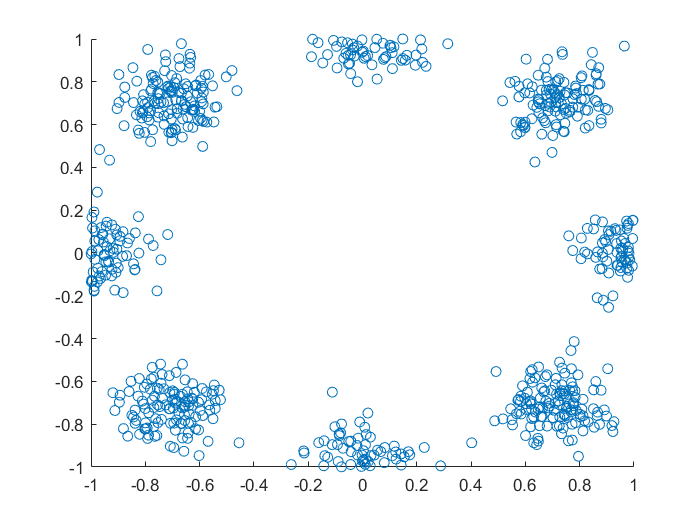

%星座图
%for i=1:L
scatter(rnI,rnQ);
axis([-1,1,-1,1]);

%end

%判决1--最大投影准则
map = [[1,0];[eb,eb];[0,1];[-eb,eb];[-1,0];[-eb,-eb];[0,-1];[eb,-eb]];
map2mapl =[1,2,4,3,8,7,5,6];

mapl = [[1,0];[eb,eb];[-eb,eb];[0,1];[eb,-eb];[0,-1];[-1,0];[-eb,-eb]];
res=mapl*[rnI,rnQ]';
[M,I]=max(res);
I

I =      5     4     1     3     8     7     6     8     1     6     1     1     6     6     8     1     4     7     2     3     8     7     2     1     8     1     5     3     5     5     8     4     5     5     8     1     6     5     6     4     3     1     5     5     4     2     3     1     1     7


sourseIndex'

ans =      5     4     1     3     8     7     6     8     1     6     1     1     6     6     8     1     4     7     2     3     8     7     2     1     8     1     5     3     5     5     8     4     5     5     8     1     6     5     6     4     3     1     5     5     4     2     3     1     1     7


%判决2--最小欧氏距离准则
index=0;
minp=100;
I2=zeros(1,L);
for i=1:L
    index=0;
    minp=100;
    for j=1:8
        if((mapl(j,1)-rnI(i))^2+(mapl(j,2)-rnQ(i))^2<minp)
            minp=(mapl(j,1)-rnI(i))^2+(mapl(j,2)-rnQ(i))^2;
            index=j;
        end
    end
    I2(i)=index;
end
I2

I2 =      5     4     1     3     8     7     6     8     1     6     1     1     6     6     8     1     4     7     2     3     8     7     2     1     8     1     5     3     5     5     8     4     5     5     8     1     6     5     6     4     3     1     5     5     4     2     3     1     1     7


sourseIndex'

ans =      5     4     1     3     8     7     6     8     1     6     1     1     6     6     8     1     4     7     2     3     8     7     2     1     8     1     5     3     5     5     8     4     5     5     8     1     6     5     6     4     3     1     5     5     4     2     3     1     1     7


%统计
%[1,2,4,3,8,7,5,6];
result = zeros(3*L,1);
for i=1:L
    switch(I2(i))
        case 1
            [result(3*i-2),result(3*i-1),result(3*i)]=fuzhi3(0,0,0);
        case 2
            [result(3*i-2),result(3*i-1),result(3*i)]=fuzhi3(0,0,1);
        case 3
            [result(3*i-2),result(3*i-1),result(3*i)]=fuzhi3(0,1,0);
        case 4
            [result(3*i-2),result(3*i-1),result(3*i)]=fuzhi3(0,1,1);
        case 5
            [result(3*i-2),result(3*i-1),result(3*i)]=fuzhi3(1,0,0);
        case 6
            [result(3*i-2),result(3*i-1),result(3*i)]=fuzhi3(1,0,1);
        case 7
            [result(3*i-2),result(3*i-1),result(3*i)]=fuzhi3(1,1,0);
        case 8
            [result(3*i-2),result(3*i-1),result(3*i)]=fuzhi3(1,1,1);  
    end
end
errorbit=0;
errornum=0;
for i=1:length(soursenum)
    if(soursenum(i)~=result(i))
        errorbit=errorbit+1;
    end
end
for i=1:length(I2)
    if(I2(i)~=sourseIndex(i))
        errornum=errornum+1;
    end
end